clear all 
clc
path = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\HPA NL Models\BER Plots\'
filename = 'ber.xls'
ber = zeros(1,7);
for backOff = [1, 7, 30]
    i = 1; %iterate through clmns
    disp(backOff)
    for EbNo = [-2, 0, 3, 10, 15, 23, 50]
        disp(EbNo)
        if backOff == 1
            GindB = -1.626571802255640;
            GoutdB = 3.911826101838731;
        elseif backOff == 7
            GindB = -7.626571802255640;
            GoutdB = 9.911826101838731;
        else 
           GindB = -30.626571802255640;
           GoutdB = 32.911826101838731;
        end 
       %run HPA and AWGN Simulations
       tic
       sim('DVB_HPA_AWGN',0.5);
       toc
       ber(i) = berVec(1); 
       i = i+1; 
    end
    writematrix(ber, [path,filename], 'Sheet', ['backOff', num2str(backOff)]) %write row to excel sheet
end 

snr = [-2, 0, 3, 10, 15, 23, 50];
awgn = [0.4, 0.3708, 0.3142, 0.1494, 0.04874, 0.00014, 0.00001];
lgd = cell(4,1);
lgd{1} = 'AWGN'

lgd = 4×1 cell array
    {'AWGN'    }
    {0×0 double}
    {0×0 double}
    {0×0 double}


i=2; 
path_f = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\HPA NL Models\BER Plots\'

path_f = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\HPA NL Models\BER Plots\'

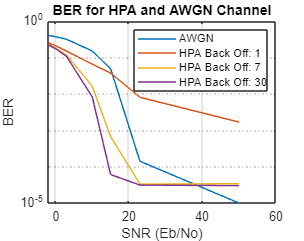

filename = 'ber.xls'; 

figure
semilogy(snr, awgn);
grid on
hold on 
xlabel('SNR (Eb/No)');
ylabel('BER');
title('BER for HPA and AWGN Channel'); 


for backOff = [1,7,30]
   ber = readmatrix([path_f,filename], 'Sheet', ['backOff', num2str(backOff)]);
   semilogy(snr, ber);
   lgd{i} = ['HPA Back Off: ', num2str(backOff)]; 
   i = i+1;
end 
legend(lgd)
hold off